# MVO-31: LAB02 - Q3

m = 390;
g = 9.8;
S = 16;
k = 0.025;
C_D0 = 0.015;
dT = 20; % Altere a atmosfera ISA aqui

C_L = [sqrt(C_D0/k) sqrt(3*C_D0/k) 0.5 1 1.4];
C_D = C_D0 + k.*C_L.^2;
E = C_L ./ C_D;

h_0 = 2000;
x_0 = 0;
v_0 = sqrt(2 * m * g ./ (densISA(h_0,dT) * S * sqrt(C_L.^2 + C_D.^2)));
gamma_0 = -atan(1./E);
t = [0 3000];

h_final = [];
x_final = [];
v_final = [];
gamma_final = [];

for i = 1:5 % Escolhendo o valor de C_L #1, #2, ... #5
    vec_0 = [h_0 x_0 v_0(i) gamma_0(i)];
    f = @(t,vec)planeio(t,vec,m,g,C_L,C_D,S,i,dT);
    [t,vec] = ode45(f,t,vec_0);
    h_final(:,i) = vec(:,1);
    x_final(:,i) = vec(:,2);
    v_final(:,i) = vec(:,3);
    gamma_final(:,i) = vec(:,4);
    idx_toque = find(h_final(:,i)==interp1(h_final(:,i),h_final(:,i),0,'nearest'));
    alcance(i) = x_final(idx_toque,i);
    autonomia(i) = t(idx_toque)/60;
end


3a)

Gráficos pedidos pelo enunciado:

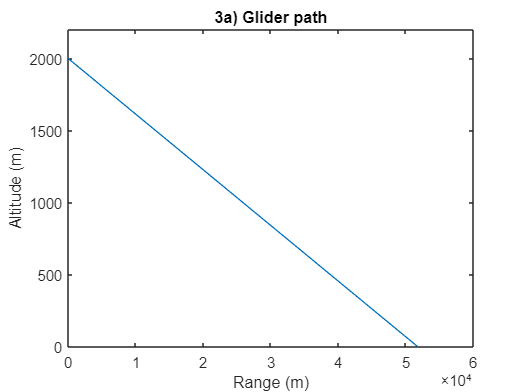

plot(x_final(:,1),h_final(:,1))
ylim([0 2200])
title("3a) Glider path")
xlabel("Range (m)")
ylabel("Altitude (m)")
hold off

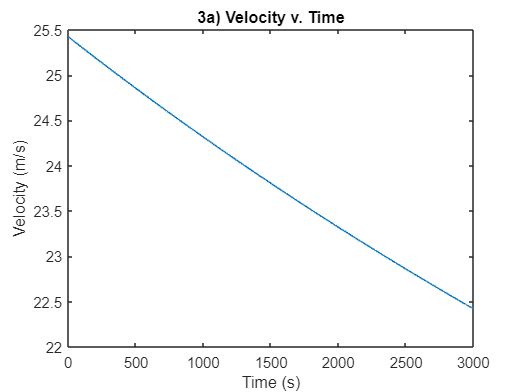


plot(t,v_final(:,1))
title("3a) Velocity v. Time")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
hold off

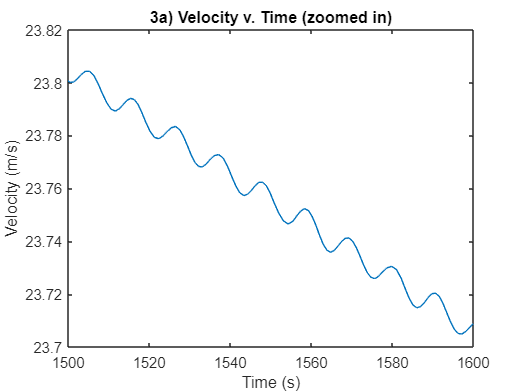


plot(t,v_final(:,1))
title("3a) Velocity v. Time (zoomed in)")
xlim([1500 1600])
xlabel("Time (s)")
ylabel("Velocity (m/s)")
hold off

3b) e 3c)

Tabela para diferentes condições de voo do planador. Altere o valor de dT para obter a tabela na atmosfera ISA+dT:

varNames = ["C_L" "E" "v_0" "gamma_0" "Alcance" "Autonomia"];
tabela_3b_3c = table(C_L',E',v_0',gamma_0',alcance',autonomia','VariableNames',varNames)

tabela_3b_3c = 5×6 table
     C_L        E        v_0       gamma_0     Alcance    Autonomia
    ______    ______    ______    _________    _______    _________

    0.7746     25.82    25.422     -0.03871     51777      35.589  
    1.3416    22.361    19.314    -0.044692     44791      40.534  
       0.5    23.529     31.64    -0.042474     47268      26.109  
         1        25    22.374    -0.039979     50111      39.139  
       1.4    21.875    18.907    -0.045682     43813      40.504  


3d)

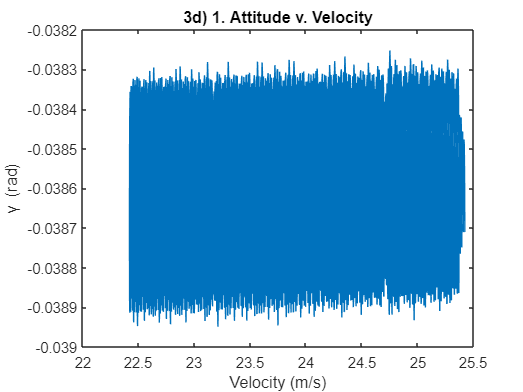

% item 1
plot(v_final(:,1),gamma_final(:,1))
title("3d) 1. Attitude v. Velocity")
ylabel("\gamma (rad)")
xlabel("Velocity (m/s)")
hold off

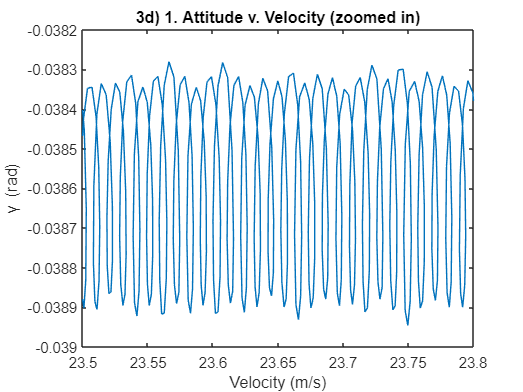


plot(v_final(:,1),gamma_final(:,1))
title("3d) 1. Attitude v. Velocity (zoomed in)")
xlim([23.5 23.8])
ylabel("\gamma (rad)")
xlabel("Velocity (m/s)")
hold off

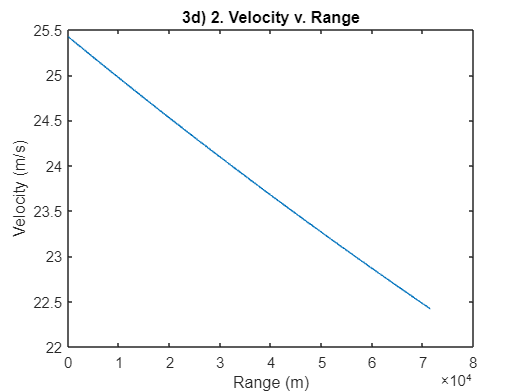


% item 2
plot(x_final(:,1),v_final(:,1))
title("3d) 2. Velocity v. Range")
xlabel("Range (m)")
ylabel("Velocity (m/s)")
hold off

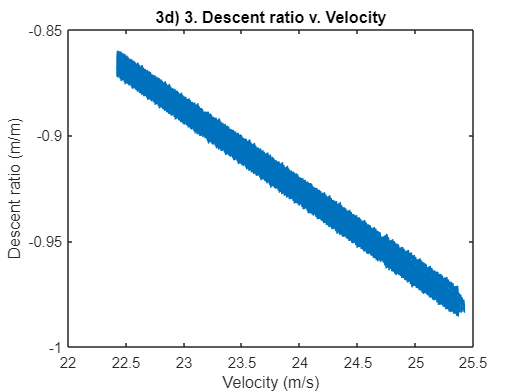


% item 3
plot(v_final(:,1),v_final(:,1).*sin(gamma_final(:,1)))
title("3d) 3. Descent ratio v. Velocity")
ylabel("Descent ratio (m/m)")
xlabel("Velocity (m/s)")
hold off

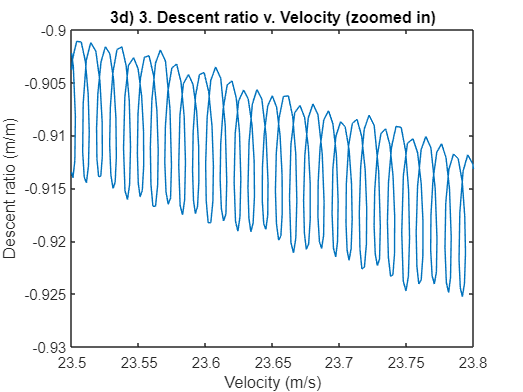

plot(v_final(:,1),v_final(:,1).*sin(gamma_final(:,1)))
title("3d) 3. Descent ratio v. Velocity (zoomed in)")
xlim([23.5 23.8])
ylabel("Descent ratio (m/m)")
xlabel("Velocity (m/s)")
hold off

function vec_P = planeio(~,vec,m,g,cl,cd,S,val,dT)
    h = vec(1);
    v = vec(3);
    gamma = vec(4);

    rho = densISA(h,dT);
    L = lift(v,cl,S,rho);
    D = drag(v,cd,S,rho);

    h_P = v * sin(gamma);
    x_P = v * cos(gamma);
    v_P = -D(val)/m - g*sin(gamma);
    gamma_P = L(val)/(m*v) - g*cos(gamma)/v;

    vec_P = [h_P x_P v_P gamma_P]';
end

function L = lift(vel,coef_L,S,rho)
    L = 0.5 * rho * vel^2 * S * coef_L;
end

function D = drag(vel,coef_D,S,rho)
    D = 0.5 * rho * vel^2 * S * coef_D;
end

function dens = densISA(height, varargin)
    % Versão modificada de "atmosferaISA()", calcula apenas
    % a densidade do ar na dada altitude
    if nargin < 2
        dT = 0;
    else
        dT = varargin{1};
    end
    T0 = 288.15 + dT;
    P0 = 101325;
    M = 0.02897;
    R = 8.314;
    L = -0.0065;
    g = 9.81;

    if height <= 11000
        temp = T0 + L*height;
        press = P0 * (temp/T0).^(-g*M/(R*L));
    elseif height <= 20000
        temp = T0 + L*11000;
        press = P0 * (temp/T0).^(-g*M/(R*L));
        press = press * exp(-g*M*(height-11000)/(R*temp));
    else
        temp = nan;
        press = nan;
    end

    dens = (press*M)/(R*temp);
end
